# Jacobi 

## Parameters

clearvars
clf
clc

set(groot,'defaultTextInterpreter','default');
% set(0,'defaultTextFontWeight','bold');
FS = 24;
set(groot,'defaultTextFontSize',FS);
set(groot,'defaultAxesFontSize',FS);
set(groot,'defaultAxesLabelFontSizeMultiplier',1);
set(groot,'defaultAxesTitleFontSizeMultiplier',1);

sympref('FloatingPointOutput',false);
u = symunit;
G = 6.6743e-11*u.m^3/u.kg/u.s^2;
pp = sym('pi',[1 2],'positive');
xi = sym('xi','real');
psi = sym('psi','real');

From stability.mlx, we have

Iu = (pp(2)/sqrt(psi^2+(xi+pp(2)-1)^2) - (pp(2)-1)/sqrt(psi^2+(xi+pp(2))^2) + (psi^2+xi^2)/2)%*(mu(1)+mu(2))/r12

$$Iu = \frac{\pi_{2}}{\sqrt{{\left(\pi_{2}+\xi -1\right)}^{2}+\psi^{2}}}-\frac{\pi_{2}-1}{\sqrt{{\left(\pi_{2}+\xi \right)}^{2}+\psi^{2}}}+\frac{\psi^{2}}{2}+\frac{\xi^{2}}{2}$$

sympref('FloatingPointOutput',true);
Iu = matlabFunction(Iu);
sys = 'EM';
if strcmp(sys,'PC')
    body{1} = 'Pluto';
    body{2} = 'Charon';
    m(1) = 1.30900e22*u.kg;
    R(1) = 1188.3e3*u.m;
    m(2) = 1.586e21*u.kg;
    R(2) = 606e3*u.m;
    M    = sum(m);
    r12  = 19640*1e3*u.m;
elseif strcmp(sys,'EM')
    body{1} = 'Earth';
    body{2} = 'Moon';
    m(1) = 5.974e24*u.kg;
    R(1) = 6378e3*u.m;
    m(2) = 7.348e22*u.kg;
    R(2) = 1737e3*u.m;
    M    = sum(m);
    r12  = 384400*1e3*u.m;
end
mu   = G*m;

## Relative positions

x12 = [-m(2) m(1)]*r12/M

$$x12 = \left(\begin{array}{cc} -4.6707e+06\,m & 3.7973e+08\,m \end{array}\right)$$

xi12 = x12/r12

$$xi12 = \left(\begin{array}{cc} -0.0122 & 0.9878 \end{array}\right)$$

## Kepler's third law

P    = sqrt(4*pi^2*r12^3 / (G*M))

$$P = 2.3570e+06\,s$$

WW    = 2*pi/P

$$WW = 2.6657e-06\,\frac{1}{s}$$

## Pseudo-potential

R1 = double(separateUnits(R(1)));
R2 = double(separateUnits(R(2)));
r12 = double(separateUnits(r12));
WW   = double(separateUnits(WW))

WW = 2.6657e-06

m1  = double(separateUnits(m(1)));
m2  = double(separateUnits(m(2)));
mu1 = double(separateUnits(mu(1)));
mu2 = double(separateUnits(mu(2)));
x1  = double(separateUnits(x12(1)))

x1 = -4.6707e+06

x2  = double(separateUnits(x12(2)))

x2 = 3.7973e+08

y1  = 0;
y2  = 0;
[xi,psi] = meshgrid(-2:0.01:2);
x    = xi*r12;
y    = psi*r12;

Normalized units

pi2 = mu2/(mu1+mu2)

pi2 = 0.0122

UU = -r12^2*WW^2*Iu(pi2,psi,xi); % J/kg
Umin = min(min(UU))

Umin = -4.8234e+08

Umax = max(max(UU))

Umax = -1.5687e+06

## Lagrange points

Based on Curtis example 2.16

xi = sym('xi');
phi = sym('phi');
p2 = sym('pi2');

f=(1-p2).*(xi+p2)./abs(xi+p2).^3 + p2.*(xi+p2-1)./abs(xi+p2-1).^3 - xi

$$f = \frac{\pi_{2}\,\left(\pi_{2}+\xi -1\right)}{{\left|\pi_{2}+\xi -1\right|}^{3}}-\xi -\frac{\left(\pi_{2}+\xi \right)\,\left(\pi_{2}-1\right)}{{\left|\pi_{2}+\xi \right|}^{3}}$$

f = matlabFunction(f)

f = function_handle with value:
    @(pi2,xi)-xi+pi2.*1.0./abs(pi2+xi-1.0).^3.*(pi2+xi-1.0)-1.0./abs(pi2+xi).^3.*(pi2+xi).*(pi2-1.0)


## Example 2.16

eps    = 1e-9;
ksi(1) = fzero(@(xi)f(pi2,xi),[-pi2+eps/10 1-pi2-eps/10]);
ups(1) = 0;
ksi(3) = fzero(@(xi)f(pi2,xi),[-2 -pi2-eps/10]);
ups(3) = 0;
ksi(2) = fzero(@(xi)f(pi2,xi),[1-pi2+eps/10 2]);
ups(2) = 0;
ksi(4)  = 1/2-pi2;
ups(4)  = sqrt(3)/2;
ksi(5)  = 1/2-pi2;
ups(5)  = -sqrt(3)/2;

### Units addition

U1 = -mu1./sqrt((x-x1).^2+(y-y1).^2);
U2 = -mu2./sqrt((x-x2).^2+(y-y2).^2);
Uw = -(x.^2+y.^2).*WW^2/2;
U  = Uw+U1+U2;
for n=1:5
    L.x(n) = ksi(n)*r12;
    L.y(n) = ups(n)*r12;
    CJ(n) = -r12^2*WW^2*Iu(pi2,ups(n),ksi(n));
end
CJ = unique(CJ);
% CJ = [1.5*CJ(1) CJ(1) CJ(2) mean(CJ(2:3)) CJ(3) mean(CJ(3:4)) CJ(4)]
CJ = [1.1*CJ(1) CJ(1) CJ(2) CJ(3) mean(CJ(3:4))]% mean(CJ(2:3)) CJ(3) CJ(4)]% mean(CJ(3:4)) CJ(4)]

CJ = 1.0e+06 *

   -1.8413   -1.6739   -1.6654   -1.5814   -1.5751


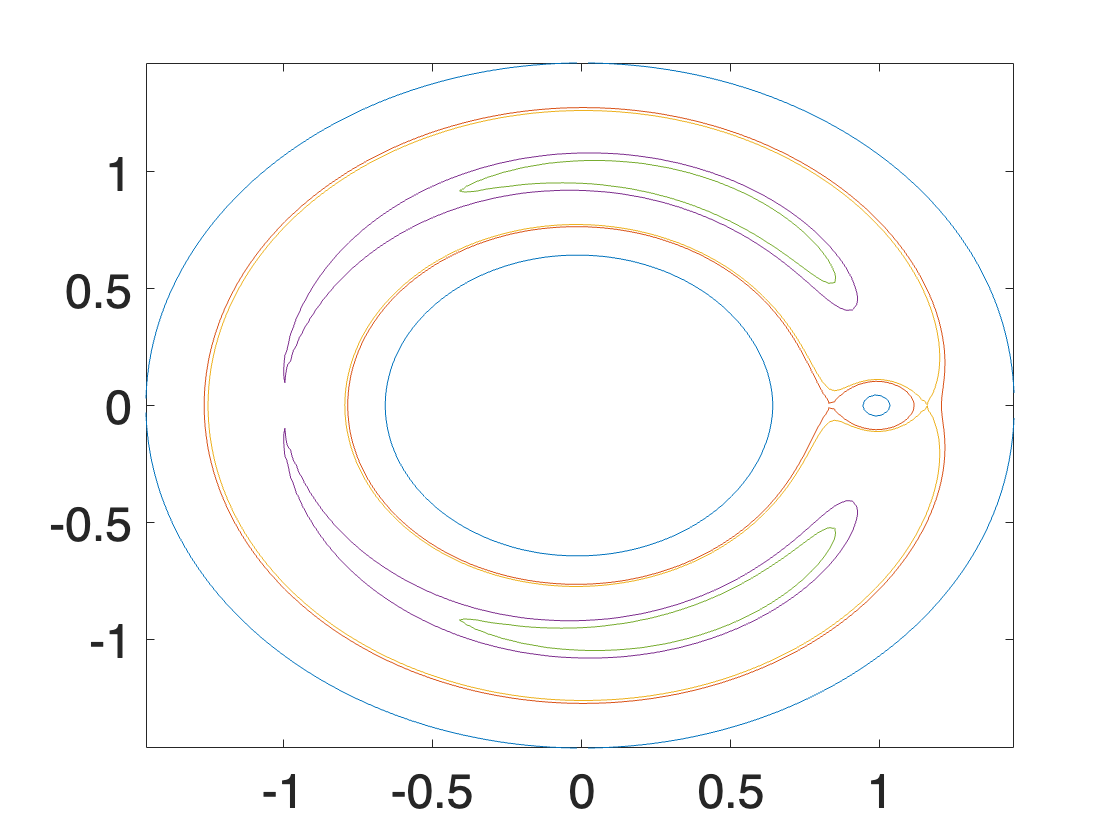



xx = sym('xx');
yy = sym('yy');
for i=1:numel(CJ)
    eq(i) = -r12^2*WW^2*Iu(pi2,yy,xx) == CJ(i);
end
fp= fimplicit(eq);

xx = [];
yy = [];
zz = [];

for i=1:numel(CJ)
    xx{i} = fp(i).XData * r12;
    yy{i} = fp(i).YData * r12;
    zz{i} = (fp(i).ZData +1)*CJ(i);
end

### Figures

[Xs,Ys,Zs] = sphere;
Xs1 = x1+Xs*R1;
Ys1 = y1+Ys*R1;
Zs1 = Zs*R1;
Xs2 = x2+Xs*R2;
Ys2 = y2+Ys*R2;
Zs2 = Zs*R2;
t = figure;
t.Units = 'normalized';
t.OuterPosition = [0 0 1 1];
map = [1 1 1; 0.8 0.8 0.8];
m=2;n=3;
tiledlayout(m,n,'TileSpacing','tight','Padding','tight')
lbl = 'abcdef';

for j=1:m*n
    ax(j)=nexttile(j);
    hold(ax(j));
    hh = -min(cell2mat(xx));
    hscale = 10^ceil(log10(hh*1e-3));
    % ax(j).XLim                  = [-hscale hscale];
    ax(j).XTick                 = (-1:.25:1)*hscale;
    ax(j).XAxis.Exponent        = 0;
    ax(j).XAxis.TickLabelFormat = '%+4.1e';
    ax(j).XLabel.String         = 'x (km)';
    
    % ax(j).YLim                  = ax(j).XLim;
    ax(j).YTick                 = ax(j).XTick;
    ax(j).YAxis.Exponent        = ax(j).XAxis.Exponent;
    ax(j).YAxis.TickLabelFormat = ax(j).XAxis.TickLabelFormat;
    ax(j).YLabel.String         = 'y (km)';
    if j>1
        ax(j).DataAspectRatio = [1 1 1];
        ax(j).XMinorTick      = 'on';
        ax(j).YMinorTick      = 'on';
        ax(j).TickDir         = 'both';
        ax(j).XAxisLocation   = "origin";
        ax(j).YAxisLocation   = "origin";
        ax(j).Box             = 'off'; 
        FZ = double((CJ(j-1)-U)<0);
        s(j) = pcolor(ax(j),x*1e-3,y*1e-3,FZ);
        shading(ax(j),"interp");
        ax(j).Colormap = map;
        set(s(j),'HandleVisibility','off','AlphaDataMapping','none','AlphaData',FZ*0.4,'FaceColor','flat','FaceAlpha','flat')
        rectangle(ax(j),'Position',[x1-R1 y1-R1 2*R1 2*R1]*1e-3,'Curvature',[1 1],'FaceColor','k','EdgeColor','k')
        rectangle(ax(j),'Position',[x2-R2 y2-R2 2*R2 2*R2]*1e-3,'Curvature',[1 1],'FaceColor','k','EdgeColor','k')
        scatter(ax(j),L.x*1e-3,L.y*1e-3,'kx');
        for i = 1:5
            text(ax(j),L.x(i)*1e-3,L.y(i)*1e-3,['L_',num2str(i)],'FontWeight','bold','HorizontalAlignment','center','VerticalAlignment','top','BackgroundColor','none')
        end
        text(ax(j),ax(j).XLim(1),ax(j).YLim(1),[' (',lbl(j),')'],'FontWeight','bold','HorizontalAlignment','left','VerticalAlignment','bottom');
        text(ax(j),x1*1e-3,y1*1e-3,{body{1};'↘︎'},'HorizontalAlignment','right','VerticalAlignment','bottom')
        text(ax(j),x2*1e-3,y2*1e-3,{body{2};'\downarrow'},'HorizontalAlignment','center','VerticalAlignment','bottom')
        title(ax(j), ['C_J=',num2str(CJ(j-1)*1e-3,'%6.1f'),' kJ/kg']);
    else
        text(ax(j),x1*1e-3,y1*1e-3,0,{body{1};'\downarrow';' '},'HorizontalAlignment','center')
        text(ax(j),x2*1e-3,y2*1e-3,0,{body{2};'\downarrow';' '},'HorizontalAlignment','center')
        for i=1:numel(CJ)
            plot3(ax(j),xx{i}*1e-3,yy{i}*1e-3,zz{i}*1e-3,'LineWidth',1.5,'DisplayName',['C_J=',num2str(CJ(i)*1e-3,'%6.1f'),' kJ/kg']);
        end
        ax(j).Box   = 'on';
        ax(j).XGrid = 'on';
        ax(j).YGrid = 'on';
        ax(j).ZGrid = 'on';
        vscale = 10^ceil(1+log10(abs(min(CJ))*1e-3));
        ax(j).ZLim                  = [-vscale 0];
        ax(j).ZTick                 = (-1:.25:0)*vscale;
        ax(j).ZAxis.Exponent        = ax(j).XAxis.Exponent;
        ax(j).ZAxis.TickLabelFormat = '%6.1d';
        ax(j).ZLabel.String         = 'U (kJ/kg)';
        ax(j).View = [10,60];
        cl = camlight(ax(j),'left');
        colormap(ax(j),gray);
        lg = legend(ax(j));
        lg.Box = "off";
        lg.Location = "northoutside";
        lg.NumColumns = 3;
        lg.AutoUpdate = 'off';
        surf(ax(j),x*1e-3,y*1e-3,U*1e-3,'FaceColor','interp','EdgeColor','none')
        text(ax(j),ax(j).XLim(1),ax(j).YLim(1),ax(j).ZLim(1),[' (',lbl(j),')'],'FontWeight','bold','HorizontalAlignment','left','VerticalAlignment','bottom');
    end
end

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held


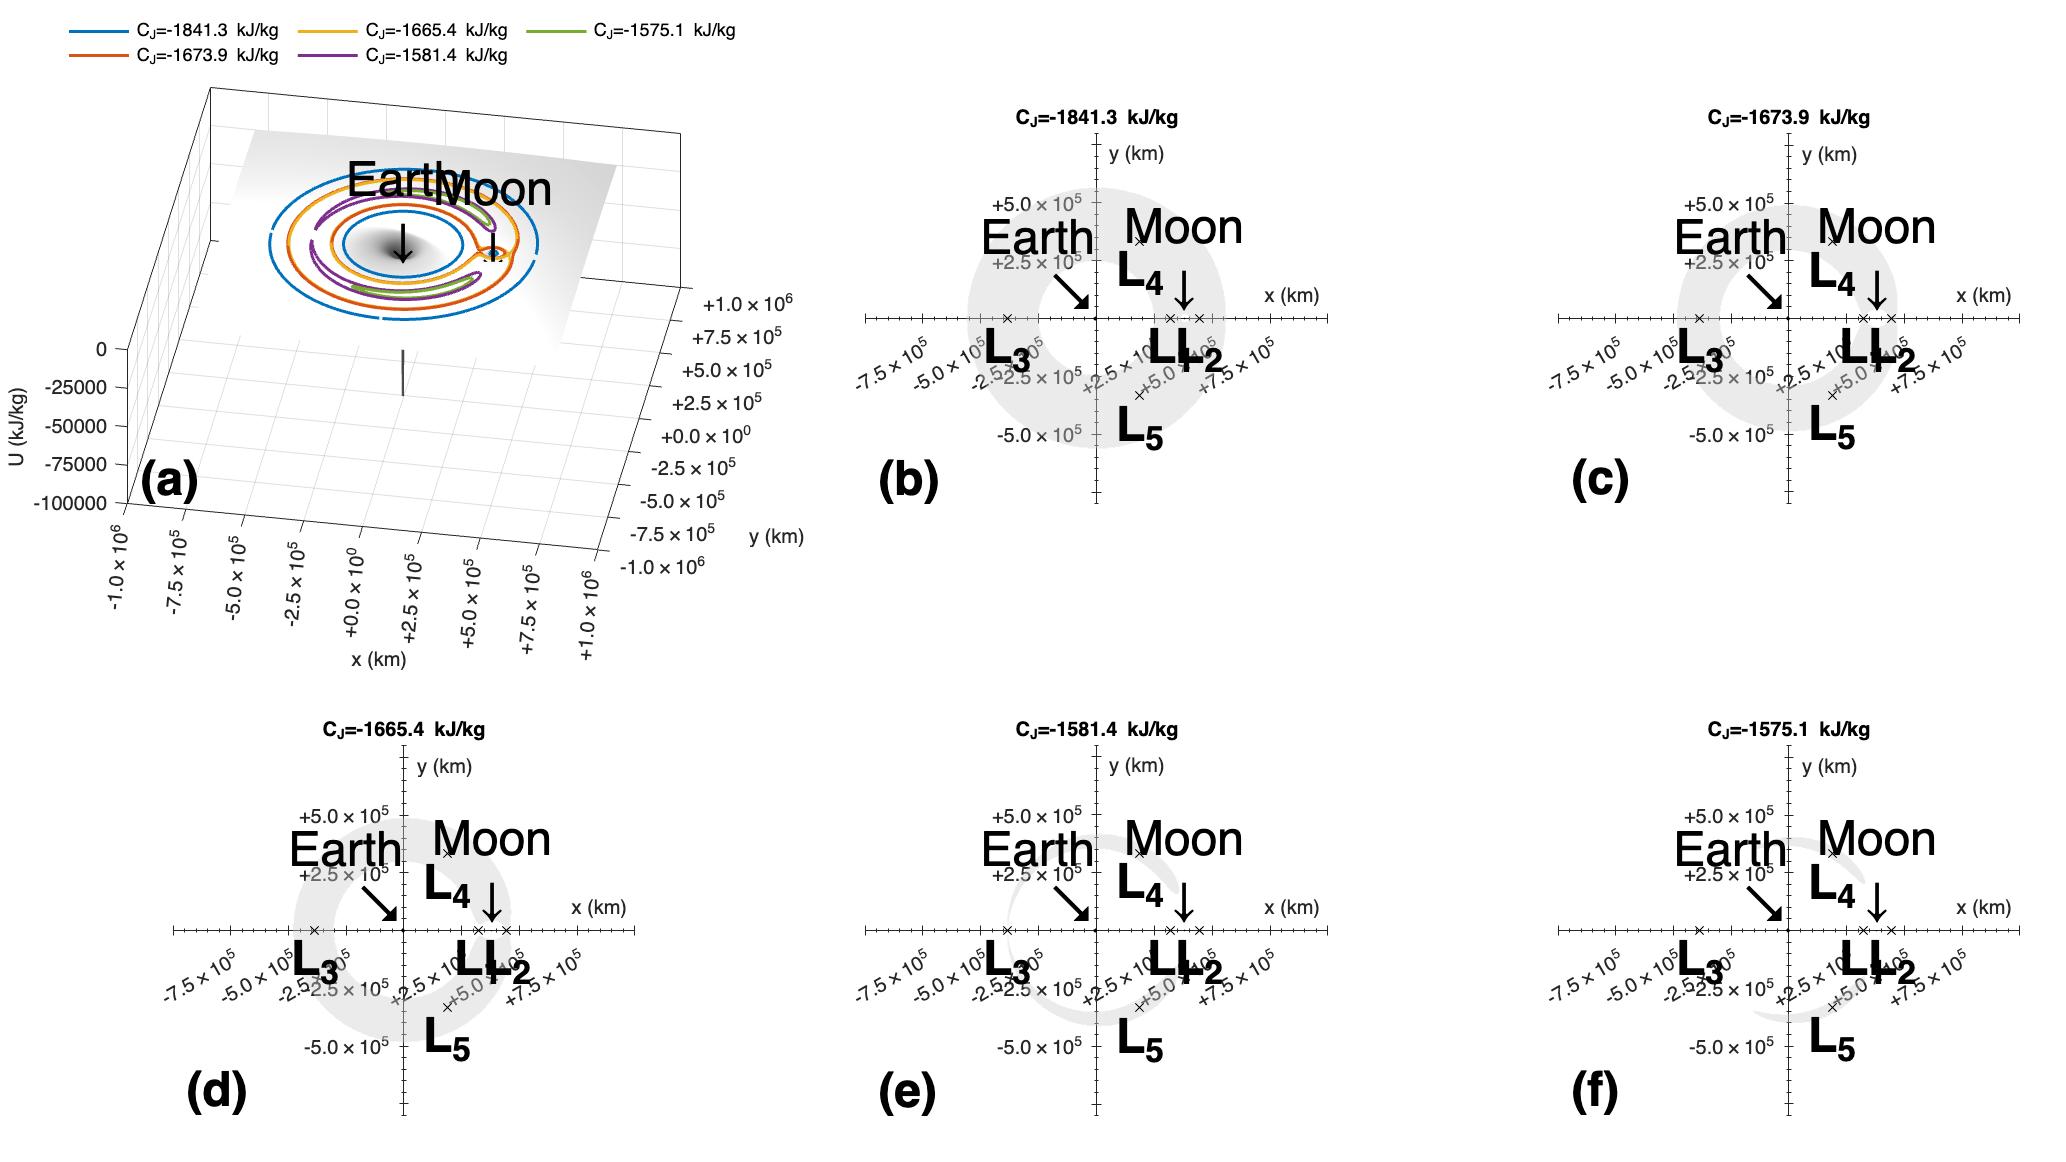

exportgraphics(t,[sys,'.pdf'],'ContentType','image','BackgroundColor','none')

savefig(t,[sys,'.fig'],"compact")